# Trim, Linearise and design a Control system for the ***Lagrangian*** quadcopter and **PENDULUM** model:

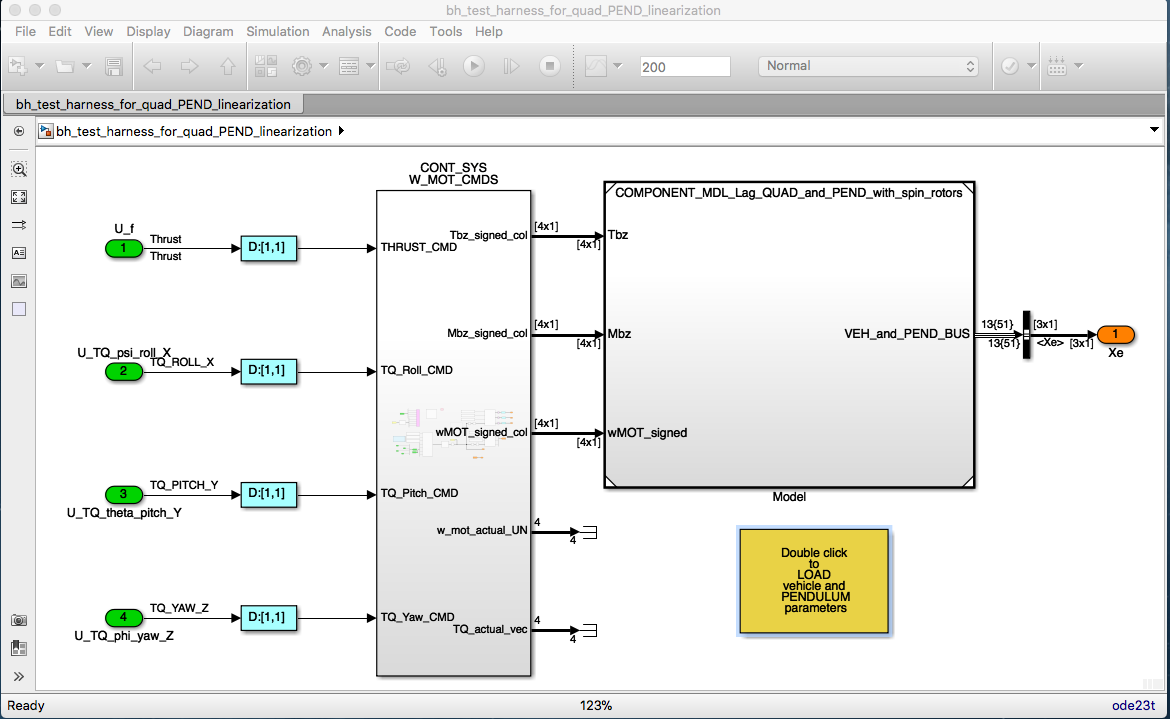

In this task we're going to linearise our **Simulink** quadcopter model. We're going to do this because we'd like to apply some "state space" control design techniques in order to design a control system for the quadcopter.  And as you know, these control techniques require a LINEAR plant model.  The workflow that we'll follow is this:

- We'll find an operating point for the pendulum. An operating point is characterized by the state(X), the input(U) and the output(Y).    We'll look specifically for an operating point that corresponds to steady state, ie: where the pendulum's state derivatives are ZERO. This is referred to as finding a **TRIMMED operating point**.

- We'll then use this TRIMMED operating point to calculate a **linearised** version of the quadcopter model.

- Finally, we'll then use this linearised model to design a full state feedback control system using the Linear Quadratic Integrator (LQI) technique.

`Bradley Horton : 08-Oct-2017, bradley.horton@mathworks.com.au`

# 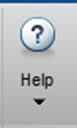 Take a moment !

If you're interested in reading about how to linearize a NON linear plant model.  Use the MATLAB HELP browser and try this simple text search

- `linearize control system`

HINT:  today we'll be using the functions:

- `operspec,   findop,   linearize`

## Load the model parameters:

bh_quad_params
bh_pend_params
bh_create_veh_and_pend_BUS

Just ensure that the the initial local Euler angles of the pendulum are ZERO:

P_pend.eul_loc_vec      = [0,0,0]'; % rad
P_veh_no_props.eul_init = [0,0,0]'; % rad

ANd echo the parameters that have been loaded into the workspace:

whos

  Name                   Size            Bytes  Class           Attributes

  PEND_BUS               1x1               310  Simulink.Bus              
  P_elec                 1x1               352  struct                    
  P_mot                  1x1              1232  struct                    
  P_mot_alone            1x1              1232  struct                    
  P_mot_vec              4x1              3584  struct                    
  P_one_prop             1x1               880  struct                    
  P_pend                 1x1               992  struct                    
  P_rot                  1x1               592  struct                    
  P_veh                  1x1              1536  struct                    
  P_veh_no_props         1x1              1536  struct                    
  VEH_AND_PEND_BUS       1x1               702  Simulink.Bus              
  XYZ_circ_mat          88x3              2112  double                    
  X_TS_OBJ              

warning('off')

## The name of the SIMULINK model that we'll linearise:

model  = 'bh_test_harness_for_quad_PEND_linearization';
open_system(model)

## Create the operating point specification object.

opspec = operspec(model);

Evaluating callback 'PostLoadFcn' for simulink
Callback: setsysloc_simulink(bdroot)
Evaluating MaskInitialization for 'bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating callback 'MaskDialog' for bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);
Evaluating MaskInitialization for 'bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating MaskInitialization for 'COMPONENT_MDL_Lag_QUAD_and_PEND_with_spin_rotors/bh_6DOF_and_pend': ' '.
Evaluating callback 'ModelCloseFcn' for simulink/Continuous/PID Controller
Callback: pidpack.PIDConfig.utilCloseTuner(gcb)
Evaluating callback 'DeleteFcn' for 

In our operating point specification, note the following:

- Our GREEN root level INPORT blocks are the system inputs 

- Our ORANGE root level OUTPORT blocks are the system outputs 

display(opspec)


 Operating point specification for the Model bh_test_harness_for_quad_PEND_linearization.
 (Time-Varying Components Evaluated at time t=0)

States: 
----------
(1.) DOT_phi
	 spec:  dx = 0,  initial guess: 0
(2.) DOT_theta
	 spec:  dx = 0,  initial guess: 0
(3.) DOT_psi
	 spec:  dx = 0,  initial guess: 0
(4.) 

For each of our model states we can specify "desired" values for each of the following.  

- `x           :`   initial guess for state value

- `SteadyState :`   a logical indicating we are looking for a dx=0 final value

- `Min         :`   minimum bound for state value

- `Max         :`   maximum bound for state value

For our problem, we're going to look for an operating point where ALL of our states are at SteadyState (ie: dx/dt=0)

%[ opspec.States(1).SteadyState]
%[ arrayfun(@(a) (a.SteadyState), opspec.States) ].'

Our trimming function(coming up next) will then look for an operating point that satisfies this specification:

## Look for the steady state operating point.

opt           = findopOptions('DisplayReport','off');
[op,opreport] = findop(model,opspec, opt);

Evaluating callback 'MaskDialog' for bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);
Evaluating MaskInitialization for 'bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating MaskInitialization for 'COMPONENT_MDL_Lag_QUAD_and_PEND_with_spin_rotors/bh_6DOF_and_pend': ' '.


Review our trimmed OPERATING point and NOTE the following:

- We have indeed found a steady state operating point because the state derivatives are either zero OR very small $O(10^{-7})$

- In this trimmed pose, ALL of the system outputs are ZERO.

- To maintain this trimmed pose we need to supply an INPUT force ... which is the force to counter gravity. 

display(opreport)


 Operating point search report for the Model bh_test_harness_for_quad_PEND_linearization.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) DOT_phi
      x:             0      dx:     -7.85e-29 (0)
(2.) DOT_theta
      x:             0      dx:      9.58e-13 (0)
(3.) DOT_psi
      x:             0      dx:     -6

## Linearize the model about this operating point:

Next we'll linearise our model about this trimmed operating point:

my_LIN_PLANT = linearize(model,op);

Evaluating callback 'MaskDialog' for bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);
Evaluating MaskInitialization for 'bh_test_harness_for_quad_PEND_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating MaskInitialization for 'COMPONENT_MDL_Lag_QUAD_and_PEND_with_spin_rotors/bh_6DOF_and_pend': ' '.


Note the names of the **INPUTS** "U"  

my_LIN_PLANT.InputName

ans = 4×1 cell array
    {'U_f'               }
    {'U_TQ_psi_roll_X'   }
    {'U_TQ_theta_pitch_Y'}
    {'U_TQ_phi_yaw_Z'    }


and the **OUTPUTS** "Y" 

my_LIN_PLANT.OutputName

ans = 3×1 cell array
    {'bh_test_harness_for_quad_PEND_linearization/Xe(1,1)'}
    {'bh_test_harness_for_quad_PEND_linearization/Xe(2,1)'}
    {'bh_test_harness_for_quad_PEND_linearization/Xe(3,1)'}


and the **STATES** "X"

my_LIN_PLANT.StateName

ans = 18×1 cell array
    {'DOT_phi'       }
    {'DOT_theta'     }
    {'DOT_psi'       }
    {'DOT_Xe'        }
    {'DOT_Ye'        }
    {'DOT_Ze'        }
    {'DOT_phi_pend'  }
    {'DOT_theta_pend'}
    {'DOT_psi_pend'  }
    {'phi'           }
    {'theta'         }
    {'psi'           }
    {'Xe'            }
    {'Ye'            }
    {'Ze'            }
    {'phi_pend'      }
    {'theta_pend'    }
    {'psi_pend'      }


Check if the linearised system is Full state Feedback(FSFB) Controllable. If the system is NOT FSFB controllable it means that we can NOT ***arbitrarily position*** the system poles.  We may still be able to position them to obtain a stable system  ... it's just that we can't arbitrarily position them.

my_LIN_PLANT = c2d(my_LIN_PLANT,1/500);

A = my_LIN_PLANT.A;
B = my_LIN_PLANT.B;
C = my_LIN_PLANT.C;
D = my_LIN_PLANT.D;

co = ctrb(A,B);
% if(rank(co) ~= size(A,1) )
%     error('###_ERROR: the system is NOT FSFB controllable');
% end

And close the model:

close_system(model)

## Control design:

We'll use the approach described by the LQI() function, ie::

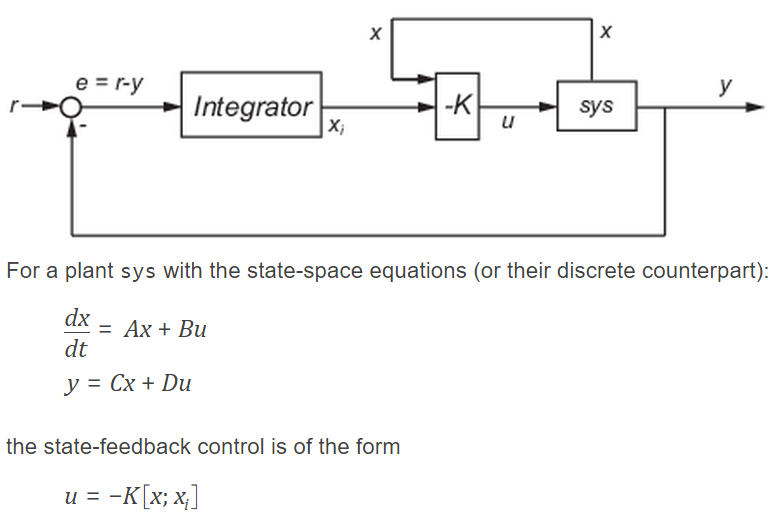

Note that:  

- 
$$K\in R^{N_u \times \left(N_x +N_y \right)}$$


Nx = size(A,1);  Nu = size(B,2);  Ny = size(C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

-  you will need to experiment with the Q,R weighting matrices

[Q,R]   = LOC_calc_Q_and_R(Nx, Ny);

[K,~,the_cl_eigs] = lqi(my_LIN_PLANT,Q,R,[])

K =    -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.8915   -0.0508   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.3377    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0639
    0.0000   -0.0000   -0.0680   -0.0000    0.0116    0.0000   -0.0014   -0.0000   -0.1744   -0.0000   -0.0000   -0.1095   -0.0000    0.0071    0.0000    0.0000   -0.0000   -1.1108    0.0000   -0.0020   -0.0000
    0.0000   -0.0680   -0.0000   -0.0116    0.0000    0.0000   -0.1570   -0.1744   -0.0000   -0.0000   -0.1095   -0.0000   -0.0071    0.0000   -0.0000   -0.0000   -1.1108   -0.0000    0.0020    0.0000   -0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


the_cl_eigs =    1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i
   0.9996 + 0.0007i
   0.9996 - 0.0007i
   0.9992 + 0.0000i
   0.9988 + 0.0024i
   0.9988 - 0.0024i
   0.9988 + 0.0024i
   0.9988 - 0.0024i


What does the gain matrix K, look like?

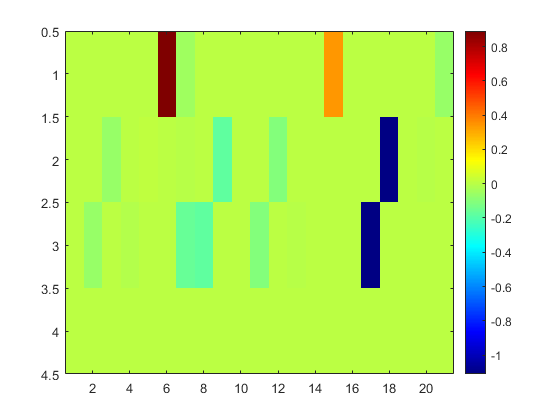

hfig = figure;
colormap(hfig,jet)
imagesc(K); colorbar

What do the closed loop poles look like ?

A_hat = [  A,   zeros(Nx,Ny);
          -C,   zeros(Ny,Ny) ];
      
B_hat = [ B;
          zeros(Ny,Nu) ];
p_lqi = esort( pole( ss((A_hat-B_hat*K),[],[],[]) ) )

p_lqi =    1.0000 + 0.0000i
   1.0000 - 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i
   0.9996 + 0.0028i
   0.9996 - 0.0028i
   0.9996 + 0.0028i
   0.9996 - 0.0028i
   0.9992 + 0.0009i
   0.9992 - 0.0009i


Now save the results:

RESULTS_FILE_NAME = 'bh_CONT_DES_RESULTS_DISCRETE.mat';
the_state_names =  my_LIN_PLANT.StateName;
save(RESULTS_FILE_NAME, 'K', 'the_state_names')

If you want to commit this design then run the following code also:

tf_i_will_commit_design = false;
if(true==tf_i_will_commit_design)
    RESULTS_FILE_NAME = 'CONFIRMED_bh_CONT_DES_RESULTS_DISCRETE.mat';
    the_state_names =  my_LIN_PLANT.StateName;
    save(RESULTS_FILE_NAME, 'K', 'the_state_names')
end

# Local Subfunctions only beyond this point

# Local Subfunctions only beyond this point

  **ATTENTION**

- The following SUB functions create the  `Q` and `R` matrices needed for the lqi() control design task.

- So how did I choose the weight for `Q` and `R` ? - In short a generated a collection of candidate designs and then applied these designs to my NONlinear model `bh_SM_quad_and_PEND.slx`.  I then "picked" a good one.  See the script file `bh_sweep_through_candidate_control_laws_CONTINUOUS.mlx`

:   **TODO**

- perform a model reduction step before doing the control design

- develop an observer to supply the new states for the design

function [Q,R] = LOC_calc_Q_and_R(Nx, Ny)

   THE_RELEASE = string (  version('-release')  );
   
   switch( upper(THE_RELEASE) )
       case "2020A"
                    [Q,R] = LOC_get_R2020a_Q_and_R(Nx, Ny);
       case "2019B"
                    [Q,R] = LOC_get_R2019b_Q_and_R(Nx, Ny);
       case "2018B"
                    [Q,R] = LOC_get_R2018b_Q_and_R(Nx, Ny);
       otherwise
           
   end
       
end

An R2020a design

function [Q,R] = LOC_get_R2020a_Q_and_R(Nx, Ny)
    
    tmp        = 1*[ones(1, Nx+Ny)];
    tmp(19:21) = [1 ,1,1000];
    Q          = diag(tmp); 
    
    tmp        = 244252*[1,1,1,1];
    R          = diag(tmp); 
    
    %[K,~,the_cl_eigs] = lqi(my_LIN_PLANT,Q,R,[])

end

:  the following `DISCRETE` design(19b) is a start. But is has a few marginally stable poles that are on the unit circle .. and you can see this margin stability in the slight oscillation of the vehicle(eg: the Simulink model `bh_SM_quad_and_PEND_discrete_CONT.slx`). So? - so a next step could involve:

function [Q,R] = LOC_get_R2019b_Q_and_R(Nx, Ny)
    
    tmp        = 1*[ones(1, Nx+Ny)];
    tmp(19:21) = [1 ,1,1000];
    Q          = diag(tmp); 
    
    tmp        = 258216*[1,1,1,1];
    R          = diag(tmp); 
    
    %[K,~,the_cl_eigs] = lqi(my_LIN_PLANT,Q,R,[])

end

: the following design was developed in R2018b.  In this release the LQI function utilised a DARE solver.  In 19a a new IMPLICIT solver IDARE was rolled out.  For my model the 18b design was a very good starting design and I've kept it here:

function [Q,R] = LOC_get_R2018b_Q_and_R(Nx, Ny)
    tmp        = 0.4*[ones(1, Nx+Ny)];
    tmp(19:21) = [0.6,0.6,1400];
    Q          = diag(tmp); 
    
    tmp        = 5e4*[1,1,1,1];  %18b - LQI uses dcare()
    R          = diag(tmp); 
    
    %[K,~,~]    = lqi(my_LIN_PLANT,Q,R,[])

end

# A diary of OLD designs:

% OK designs
% tmp        = 0.3*[ones(1, Nx+Ny)];
% Q = diag(tmp); 
% tmp = 5e4*[1,1,1,1];  %18b
% R = diag(tmp); 
%------------------------------------------
% tmp        = 0.3*[ones(1, Nx+Ny)];
% tmp(19:21) = 0.3*[1,1,555];
% Q = diag(tmp); 
% tmp = 5e4*[1,1,1,1];  %18b
% R = diag(tmp); 
%------------------------------------------
% dt=1/500;
% tmp        = 0.5*[ones(1, Nx+Ny)];
% tmp(19:21) = 1*[0.5,0.5,22];
% %tmp(21) = 50;
% Q = diag(tmp); 
% tmp = 5e4*[1,1,1,1];  %18b
% R = diag(tmp); 
%------------------------------------------
% dt=1/500;
% tmp        = 0.5*[ones(1, Nx+Ny)];
% tmp(19:21) = 1*[0.5,0.5,999];
% %tmp(21) = 50;
% Q = diag(tmp); 
% tmp = 5e4*[1,1,1,1];  %18b
% R = diag(tmp); 
%------------------------------------------
% tmp        = 0.5*[ones(1, Nx+Ny)];
% tmp(19:21) = 1*[0.7,0.7,999];
% %tmp(21) = 50;
% Q = diag(tmp); 
% tmp = 5e4*[1,1,1,1];  %18b
%------------------------------------------
% dt=1/500:  *LEADER
% tmp        = 0.4*[ones(1, Nx+Ny)];
% %tmp(19:21) = 0.5*[3,3,1222];
% tmp(21) = 1500;
% Q = diag(tmp); 
% tmp = 5e4*[1,1,1,1];  %18b
% R = diag(tmp); 
%------------------------------------------
% tmp        = 0.4*[ones(1, Nx+Ny)];
% tmp(19:21) = [0.4,0.4,1200];
% %tmp(21) = 2200;
% Q = diag(tmp); 
% tmp = 5e4*[1,1,1,1];  %18b
% R = diag(tmp); 
%------------------------------------------